% add path to functions/scripts
addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\KC_thresh_functions

% load individual vars into group cell arrays
[nGroup, nthVarsFilePaths, groupStimDetails, groupSubjData, groupSubjName, groupDate, groupTrialCond, groupNumPreStimFrames, groupNumPostStimFrames, groupIdxOnsetsMeetsCriteria, groupOnsetDf, groupPeakFrameIdx, groupStimOnsetFrame, groupBaselineIdx, groupBaselinedActIm, groupRoundXpts, groupRoundYpts, groupPTSdfof, groupMeanSpeedAllTrials, groupIdxRunTrials, groupIdxStatTrials, groupIdxSmallPupilTrials, groupIdxLargePupilTrials, groupLongAxis, groupMeanPupilDiameterAllTrials, groupRunThresh, groupPupThresh] = makeGroupStruct();
% of no pup data:
%[nGroup, nthVarsFilePaths, groupStimDetails, groupSubjData, groupSubjName, groupDate, groupTrialCond, groupNumPreStimFrames, groupNumPostStimFrames, groupIdxOnsetsMeetsCriteria, groupOnsetDf, groupPeakFrameIdx, groupStimOnsetFrame, groupBaselineIdx, groupBaselinedActIm, groupRoundXpts, groupRoundYpts, groupPTSdfof, groupMeanSpeedAllTrials, groupIdxRunTrials, groupIdxStatTrials, groupRunThresh] = makeGroupStruct_noPup();

% get stim conditions in order of trial & list of stim params to loop thru
% (This needs to be done new w/in the loop too each sess since the order of trialCond matters.. right now it's jsut to define cont & durat etc)
n = 1;
[durOrderedByTrialMeetCriteria,uniqueDurations,conOrderedByTrialMeetCriteria,uniqueContrasts,conAndDurOrderedByTrialMeetCriteria] = getStimParams4loops(n,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria);

% in preparation for making pixel wise figures of fluorescene at different stim conditions,
% make figure legends
[reigons,cons4Legend,cons4axes,durs4Legend,durs4Axes] = getSubtitleLegendNaxesInfo(uniqueContrasts,uniqueDurations);
reigons

reigons =     'V1'    'LP-HVA'    'LA-HVA'    'MA-HVA'    'control'


cons4Legend

cons4Legend =     '0'    '0.03'    '0.0625'    '0.125'    '0.25'    '0.5'    '1'


durs4Legend 

durs4Legend =     '6'


% CRFs

% which areas/stimulus parameters to loop over:

n = 1; % this is just to get the number of points
visArea = 1:length(groupRoundXpts{1,n})

visArea =      1     2     3     4     5


%visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control

%durat = 1:length(uniqueDurations)
durat = 1 % ( durat = 1 means 100 ms in final set of expts)

durat =      1



cont = 1:length(uniqueContrasts)

cont =      1     2     3     4     5     6     7


%cont = 7;

% LOCO NO PUP

% stat group CRF matrix
state = 'loRun'

state = loRun

clear loRun_allSessAllPtsAllDurs_CRF
[loRun_allSessAllPtsAllDurs_CRF] = CRF_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% duration x contrasts x points x sessions
sizeloRunAllSessAllPtsAllDurs_CRF = size(loRun_allSessAllPtsAllDurs_CRF)

sizeloRunAllSessAllPtsAllDurs_CRF =      1     7     5     3


state = 'hiRun'

state = hiRun

clear hiRun_allSessAllPtsAllDurs_CRF
[hiRun_allSessAllPtsAllDurs_CRF] = CRF_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeHiRunAllSessAllPtsAllDurs_CRF = size(hiRun_allSessAllPtsAllDurs_CRF)

sizeHiRunAllSessAllPtsAllDurs_CRF =      1     7     5     3


% for crf figs
yMax = 0.1;
yMin = -0.01;
yLimit = [yMin yMax];
x_axis = [1:length(uniqueContrasts)];
xMax = max(x_axis);
xMin = min(x_axis);
xLimit = [xMin xMax];

% PLOT locomotion CRF
stateLegend = {'stat','run'}

stateLegend =     'stat'    'run'


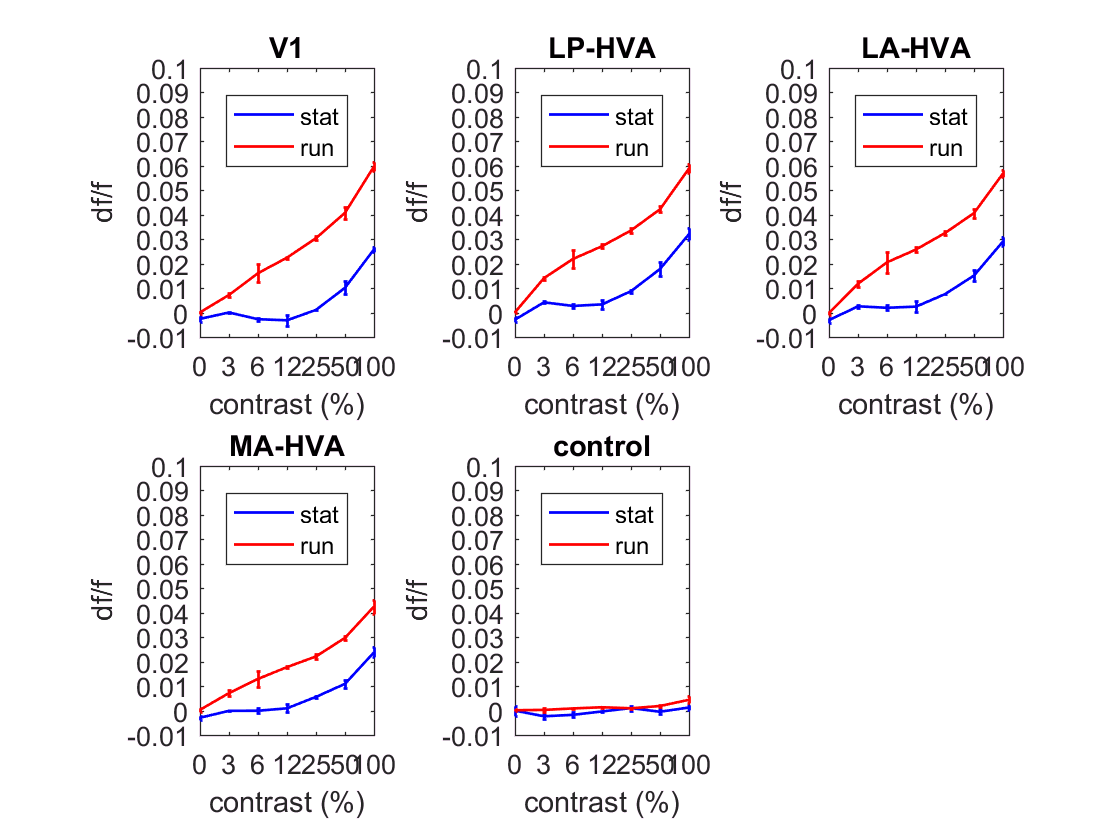

plotCompareBehState_CRF(loRun_allSessAllPtsAllDurs_CRF,hiRun_allSessAllPtsAllDurs_CRF,durat,yMax,yMin,yLimit,x_axis,xMax,xMin,xLimit,stateLegend,uniqueContrasts,reigons,nGroup);

% LOCO w/PUP

% stat group CRF matrix
state = 'loRun'
clear loRun_allSessAllPtsAllDurs_CRF
[loRun_allSessAllPtsAllDurs_CRF] = CRF_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeStatAllSessAllPtsAllDurs_CRF = size(loRun_allSessAllPtsAllDurs_CRF)

% run group CRF matrix
state = 'hiRun'
clear hiRun_allSessAllPtsAllDurs_CRF
[hiRun_allSessAllPtsAllDurs_CRF] = CRF_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeRunAllSessAllPtsAllDurs_CRF = size(hiRun_allSessAllPtsAllDurs_CRF)

% for crf figs
yMax = 0.1;
yMin = -0.01;
yLimit = [yMin yMax];
x_axis = [1:length(uniqueContrasts)];
xMax = max(x_axis);
xMin = min(x_axis);
xLimit = [xMin xMax];

%PLOT locomotion CRF
stateLegend = {'stat','run'}
plotCompareBehState_CRF(loRun_allSessAllPtsAllDurs_CRF,hiRun_allSessAllPtsAllDurs_CRF,durat,yMax,yMin,yLimit,x_axis,xMax,xMin,xLimit,stateLegend,uniqueContrasts,reigons,nGroup);

% lo pup group CRF matrix
state = 'loPup'
clear loPup_allSessAllPtsAllDurs_CRF
[loPup_allSessAllPtsAllDurs_CRF] = CRF_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeLoPupAllSessAllPtsAllDurs_CRF = size(loPup_allSessAllPtsAllDurs_CRF)

% hi pup group CRF matrix
state = 'hiPup'
clear hiPup_allSessAllPtsAllDurs_CRF
[hiPup_allSessAllPtsAllDurs_CRF] = CRF_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeHiPupAllSessAllPtsAllDurs_CRF = size(hiPup_allSessAllPtsAllDurs_CRF)

% crf pup figs 
stateLegend = {'loPup','hiPup'}
plotCompareBehState_CRF(loPup_allSessAllPtsAllDurs_CRF,hiPup_allSessAllPtsAllDurs_CRF,durat,yMax,yMin,yLimit,x_axis,xMax,xMin,xLimit,stateLegend,uniqueContrasts,reigons,nGroup);

% NEW 031422
% get max DF in loBehState = mean DF for 100% contrast in lo beh state sessions
visArea = 1;
durat = 1;
cont = 7; % max cont

mnDFcon100loBehState = mean(squeeze(loRun_allSessAllPtsAllDurs_CRF(durat,cont,visArea,:))');
mnDFcon100loBehState

% get mn CRF across sessions for 1 vis area, hi beh state
mn_hiRun_allSessOnePtsAllDurs_CRF = mean(squeeze(hiRun_allSessAllPtsAllDurs_CRF(durat,:,visArea,:))',1)

% Find lowest Con where DF hiBehState > DF mnDFcon100loBehState
conWhereHiStateGreaterOrEqualToLoMax = uniqueContrasts(min(find(mn_hiRun_allSessOnePtsAllDurs_CRF >= mnDFcon100loBehState)))
dfAt_ConWhereHiStateGreaterOrEqualToLoMax = hiRun_allSessAllPtsAllDurs_CRF(min(find(mn_hiRun_allSessOnePtsAllDurs_CRF >= mnDFcon100loBehState)))

maxLoStateCon = 1;
y = [maxLoStateCon, conWhereHiStateGreaterOrEqualToLoMax]
figure
bar(y)
title('Contrast where DF hiBehState (R) exceeds maxDFLoBehState (L)')

% NEW 031521

% LO BEH STATE

% What is the lowest con w/sig diff in DF from c=0?

% dur x con x point x sessions
sizeloRunAllSessAllPtsAllDurs_CRF = size(loRun_allSessAllPtsAllDurs_CRF)


% one dur, one con one point, one session

format long g % no sci notation

visArea = 1;
durat = 1;
cont = 1; % max cont

% the mean dF at C = n, for all sessions, one point & dur
% 1 x # sessions
mnDfs_con1onePtOneDursAllSess = squeeze(loRun_allSessAllPtsAllDurs_CRF(durat,cont,visArea,:))'

mnDfs_con1onePtOneDursAllSess =     -0.002477881    -0.004627586   -0.0006461795


mnDf_con1onePtOneDursAcrossSess = mean(mnDfs_con1onePtOneDursAllSess)

mnDf_con1onePtOneDursAcrossSess =     -0.002583882



cont = 2 

cont =      2


mnDfs_con2onePtOneDursAllSess = squeeze(loRun_allSessAllPtsAllDurs_CRF(durat,cont,visArea,:))'

mnDfs_con2onePtOneDursAllSess =     0.0001842855    0.0001078993   -0.0002262145


mnDf_con2onePtOneDursAcrossSess = mean(mnDfs_con2onePtOneDursAllSess)

mnDf_con2onePtOneDursAcrossSess =     2.199008e-05



cont = 3 

cont =      3


mnDfs_con3onePtOneDursAllSess = squeeze(loRun_allSessAllPtsAllDurs_CRF(durat,cont,visArea,:))'

mnDfs_con3onePtOneDursAllSess =     -0.001557733    -0.003393369    -0.003201283


mnDf_con3onePtOneDursAcrossSess = mean(mnDfs_con3onePtOneDursAllSess)

mnDf_con3onePtOneDursAcrossSess =     -0.002717461



cont = 4 

cont =      4


mnDfs_con4onePtOneDursAllSess = squeeze(loRun_allSessAllPtsAllDurs_CRF(durat,cont,visArea,:))'

mnDfs_con4onePtOneDursAllSess =    -0.0005424246     -0.00771842     -0.00126723


mnDf_con4onePtOneDursAcrossSess = mean(mnDfs_con4onePtOneDursAllSess)

mnDf_con4onePtOneDursAcrossSess =     -0.003176025



cont = 5

cont =      5


mnDfs_con5onePtOneDursAllSess = squeeze(loRun_allSessAllPtsAllDurs_CRF(durat,cont,visArea,:))'

mnDfs_con5onePtOneDursAllSess =       0.00103526    0.0008509401      0.00138142


mnDf_con5onePtOneDursAcrossSess = mean(mnDfs_con5onePtOneDursAllSess)

mnDf_con5onePtOneDursAcrossSess =      0.001089207



cont = 6

cont =      6


mnDfs_con6onePtOneDursAllSess = squeeze(loRun_allSessAllPtsAllDurs_CRF(durat,cont,visArea,:))'

mnDfs_con6onePtOneDursAllSess =      0.007483898     0.007607449      0.01528577


mnDf_con6onePtOneDursAcrossSess = mean(mnDfs_con6onePtOneDursAllSess)

mnDf_con6onePtOneDursAcrossSess =       0.01012571



cont = 7

cont =      7


mnDfs_con7onePtOneDursAllSess = squeeze(loRun_allSessAllPtsAllDurs_CRF(durat,cont,visArea,:))'

mnDfs_con7onePtOneDursAllSess =       0.02370753      0.02608482      0.02772611


mnDf_con7onePtOneDursAcrossSess = mean(mnDfs_con7onePtOneDursAllSess)

mnDf_con7onePtOneDursAcrossSess =       0.02583949


% t-test of mean df across sessions for each con

n_cons = 7 % # contrasts 

n_cons =      7


denom = n_cons-1 % # comparisons

denom =      6


alf = 0.05/denom % bonferroni correction for multiple comparisons

alf =        0.00833333333333333


% needs range of samples (one for each session, a vector) not just individual variables:

[h,p] = ttest(mnDfs_con1onePtOneDursAllSess,mnDfs_con2onePtOneDursAllSess,'Alpha',alf)

h =      1


p =      0.002453025



[h,p] = ttest(mnDfs_con1onePtOneDursAllSess,mnDfs_con3onePtOneDursAllSess,'Alpha',alf)

h =      1


p =       0.00351761



[h,p] = ttest(mnDfs_con1onePtOneDursAllSess,mnDfs_con4onePtOneDursAllSess,'Alpha',alf)

h =      0


p =      0.008913208



[h,p] = ttest(mnDfs_con1onePtOneDursAllSess,mnDfs_con5onePtOneDursAllSess,'Alpha',alf)

h =      1


p =      0.001924567



[h,p] = ttest(mnDfs_con1onePtOneDursAllSess,mnDfs_con6onePtOneDursAllSess,'Alpha',alf)

h =      0


p =       0.01233125



[h,p] = ttest(mnDfs_con1onePtOneDursAllSess,mnDfs_con7onePtOneDursAllSess,'Alpha',alf)

h =    NaN


p =    NaN


% HI BEH STATE

% What is the lowest con w/sig diff in DF from c=0?

% dur x con x point x sessions
sizeloRunAllSessAllPtsAllDurs_CRF = size(hiRun_allSessAllPtsAllDurs_CRF)


% one dur, one con one point, one session

format long g % no sci notation

visArea = 1;
durat = 1;
cont = 1; % max cont

% the mean dF at C = n, for all sessions, one point & dur
% 1 x # sessions
mnDfs_con1onePtOneDursAllSess = squeeze(hiRun_allSessAllPtsAllDurs_CRF(durat,cont,visArea,:))'
mnDf_con1onePtOneDursAcrossSess = mean(mnDfs_oneCon1onePtOneDursAllSess)

cont = 2 
mnDfs_con2onePtOneDursAllSess = squeeze(hiRun_allSessAllPtsAllDurs_CRF(durat,cont,visArea,:))'
mnDf_con2onePtOneDursAcrossSess = mean(mnDfs_con2onePtOneDursAllSess)

cont = 3 
mnDfs_con3onePtOneDursAllSess = squeeze(hiRun_allSessAllPtsAllDurs_CRF(durat,cont,visArea,:))'
mnDf_con3onePtOneDursAcrossSess = mean(mnDfs_con2onePtOneDursAllSess)

cont = 4 
mnDfs_con4onePtOneDursAllSess = squeeze(hiRun_allSessAllPtsAllDurs_CRF(durat,cont,visArea,:))'
mnDf_con4onePtOneDursAcrossSess = mean(mnDfs_con2onePtOneDursAllSess)

cont = 5
mnDfs_con5onePtOneDursAllSess = squeeze(hiRun_allSessAllPtsAllDurs_CRF(durat,cont,visArea,:))'
mnDf_con5onePtOneDursAcrossSess = mean(mnDfs_con2onePtOneDursAllSess)

cont = 6
mnDfs_con6onePtOneDursAllSess = squeeze(hiRun_allSessAllPtsAllDurs_CRF(durat,cont,visArea,:))'
mnDf_con6onePtOneDursAcrossSess = mean(mnDfs_con2onePtOneDursAllSess)

cont = 7
mnDfs_con7onePtOneDursAllSess = squeeze(hiRun_allSessAllPtsAllDurs_CRF(durat,cont,visArea,:))'
mnDf_con7onePtOneDursAcrossSess = mean(mnDfs_con2onePtOneDursAllSess)

% t-test of mean df across sessions for each con

n_cons = 7 % # contrasts 
denom = n_cons-1 
alf = 0.05/denom % bonferroni correction for multiple comparisons

format long g

[h,p,] = ttest(mnDfs_con1onePtOneDursAllSess,mnDfs_con2onePtOneDursAllSess,'Alpha',alf)

[h,p,] = ttest(mnDfs_con1onePtOneDursAllSess,mnDfs_con3onePtOneDursAllSess,'Alpha',alf)

[h,p,] = ttest(mnDfs_con1onePtOneDursAllSess,mnDfs_con4onePtOneDursAllSess,'Alpha',alf)

[h,p,] = ttest(mnDfs_con1onePtOneDursAllSess,mnDfs_con5onePtOneDursAllSess,'Alpha',alf)

[h,p,] = ttest(mnDfs_con1onePtOneDursAllSess,mnDfs_con6onePtOneDursAllSess,'Alpha',alf)

[h,p,ci,stats] = ttest(mnDfs_con1onePtOneDursAllSess,mnDfs_con7onePtOneDursAllSess,'Alpha',alf)


[h,p,] = ttest(mnDfs_con1onePtOneDursAllSess,mnDfs_con1onePtOneDursAllSess,'Alpha',alf)

% pseudo code - using group CRF matricies

% for each beh state,
% for each duration (only 1 tho),
% for each visual area, 
% take the mean df at each contrast across all mice (mean of mean)
% for each con, use t test to compare mean df between c = 0 and cth con
% collect in 1 x 7 output vector for each beh state

% for each beh state,
% for cons where h = 1
% collect cont ('c') value

% scatter plot - like CRF but w/asterisks
% series (red vs blue = beh states)
% y = df value
% x = con
% asterisk = sig from zero

% categorical - bar or scatter plot w/2 asterisks?
% for each beh state,
% plot mean of 1st sig diff con (needs 1 x 2 matrix with mean 1st sig diff con 
% for lo beh state & same for hi beh state)
% y = mean con of 1st sig diff con
% x = 2 categories: lo Beh State vs Hi Beh State
% plot mean 1st sig df con 


% NEW 031622

visArea = 1:length(groupRoundXpts{1,n})

visArea =      1     2     3     4     5


%visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control

%durat = 1:length(uniqueDurations)
durat = 1 % ( durat = 1 means 100 ms in final set of expts)

durat =      1



cont = 1:length(uniqueContrasts)

cont =      1     2     3     4     5     6     7


%cont = 7;


% get mean CRF across sessions (another function does this then plots it, this function just does it and gives output var)
% loRun 
[mnCRF_acrossSess_AllDurAllPts_loBehState] = mean_CRF_AcrossSessions(loRun_allSessAllPtsAllDurs_CRF,visArea,durat,cont);
% gives 1 x contrast
size(mnCRF_acrossSess_AllDurAllPts_loBehState)

ans =      5     7



% hiRun
[mnCRF_acrossSess_AllDurAllPts_hiBehState] = mean_CRF_AcrossSessions(hiRun_allSessAllPtsAllDurs_CRF,visArea,durat,cont);
size(mnCRF_acrossSess_AllDurAllPts_hiBehState)

ans =      5     7


% picking an alpha value (correct for mult. comparisons)
n_cons = 7 % # contrasts 

n_cons =      7


denom = n_cons-1 % # comparisons

denom =      6


alf = 0.05/denom % bonferroni correction for multiple comparisons

alf =        0.00833333333333333


% STATS

% FOR LO BEH STATE

% making matrix with all stats for all pairs of c=0 and other c's for each area & duration
clear h_p_cil_cih_AllPairs_AllPts_AllDurs

% for each duration
clear d
for d = durat 
    
    % new comparisons for each duration
    clear h_p_cil_cih_AllPairs_AllPts

    % for each visual area
    clear i
    for i = visArea
        
        % new contrast comparison for each vis area
        clear h_p_cil_cih_AllPairs

        % for each contrast * except c = 0 (cuz will get N/A)
        clear c
        for c = cont(2:end)
            
            % check for sig diff between cth contrast & c = 0 
            [h,p,ci] = ttest(mean(squeeze(loRun_allSessAllPtsAllDurs_CRF(1,1,i,:))',1),mean(squeeze(loRun_allSessAllPtsAllDurs_CRF(1,c,i,:))',1),'Alpha',alf);
            
            h_p_cil_cih_AllPairs(1,c-1) = h; % c-1 so index doesn't start at 2
            h_p_cil_cih_AllPairs(2,c-1) = p;
            h_p_cil_cih_AllPairs(3,c-1) = ci(1,1);
            h_p_cil_cih_AllPairs(4,c-1) = ci(1,2);
            
        end % end contrast loop
        
        % collect stats x contrast grid for each point
        h_p_cil_cih_AllPairs_AllPts(:,:,i) = h_p_cil_cih_AllPairs;
        
    end % end points loop
    
    h_p_cil_cih_AllPairs_AllPts_AllDurs(:,:,:,d) = h_p_cil_cih_AllPairs_AllPts;
    
end % end dur loop
        
% stats param x comparison contrast x points
loBehState_h_p_cil_cih_AllPairs_AllPts_AllDurs = h_p_cil_cih_AllPairs_AllPts_AllDurs;
size(loBehState_h_p_cil_cih_AllPairs_AllPts_AllDurs)

ans =      4     6     5


% STATS

% FOR HI BEH STATE

% making matrix with all stats for all pairs of c=0 and other c's for each area & duration
clear h_p_cil_cih_AllPairs_AllPts_AllDurs

% for each duration
clear d
for d = durat 
    
    % new comparisons for each duration
    clear h_p_cil_cih_AllPairs_AllPts

    % for each visual area
    clear i
    for i = visArea
        
        % new contrast comparison for each vis area
        clear h_p_cil_cih_AllPairs

        % for each contrast * except c = 0 (cuz will get N/A)
        clear c
        for c = cont(2:end)
            
            % check for sig diff between cth contrast & c = 0 
            [h,p,ci] = ttest(mean(squeeze(hiRun_allSessAllPtsAllDurs_CRF(1,1,i,:))',1),mean(squeeze(hiRun_allSessAllPtsAllDurs_CRF(1,c,i,:))',1),'Alpha',alf);
            
            h_p_cil_cih_AllPairs(1,c-1) = h; % c-1 so index doesn't start at 2
            h_p_cil_cih_AllPairs(2,c-1) = p;
            h_p_cil_cih_AllPairs(3,c-1) = ci(1,1);
            h_p_cil_cih_AllPairs(4,c-1) = ci(1,2);
            
        end % end contrast loop
        
        % collect stats x contrast grid for each point
        h_p_cil_cih_AllPairs_AllPts(:,:,i) = h_p_cil_cih_AllPairs;
        
    end % end points loop
    
    h_p_cil_cih_AllPairs_AllPts_AllDurs(:,:,:,d) = h_p_cil_cih_AllPairs_AllPts;
    
end % end dur loop
        
% stats param x comparison contrast x points
hiBehState_h_p_cil_cih_AllPairs_AllPts_AllDurs = h_p_cil_cih_AllPairs_AllPts_AllDurs;
size(hiBehState_h_p_cil_cih_AllPairs_AllPts_AllDurs)

ans =      4     6     5


visArea = 1:length(groupRoundXpts{1,n})

visArea =      1     2     3     4     5



durat = 1 % ( durat = 1 means 100 ms in final set of expts)

durat =      1



cont = 1:length(uniqueContrasts)

cont =      1     2     3     4     5     6     7


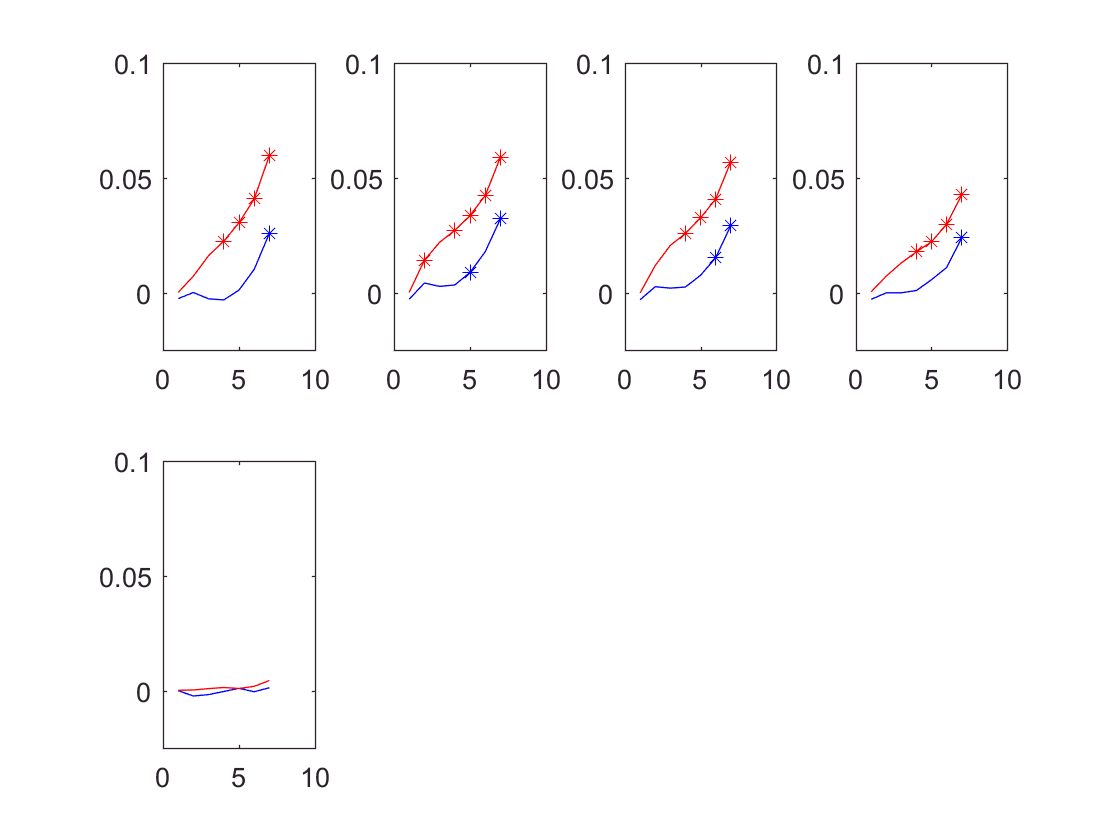

% PLOT w/asterisk if sig from c=0

figure

% for each duration
clear d
for d = durat

    % for each point
    clear i
    for i = visArea
        
        % Plot the CRF for LO beh state
        
        % make a sub plot
        subplot(2,4,i)
        x_axis = 1:length(uniqueContrasts);
        plot(x_axis,mnCRF_acrossSess_AllDurAllPts_loBehState(i,:),'b')
        
        hold on
        
        % for each comparison, if h ==1, overlay a star (colored)
        clear com
        for com = 1:length(loBehState_h_p_cil_cih_AllPairs_AllPts_AllDurs)
            
            if loBehState_h_p_cil_cih_AllPairs_AllPts_AllDurs(1,com,i) == 1
                
                plot(com+1,mnCRF_acrossSess_AllDurAllPts_loBehState(i,com+1),'b*')
                
                hold on
           
            end % end if statement
            
        end % end com loop
        
        hold on
        
        % plot HI beh state CRF
        plot(x_axis,mnCRF_acrossSess_AllDurAllPts_hiBehState(i,:),'r')
        ylim([-0.025 0.1])
        
        hold on
        
        % for each comparison, if h ==1, overlay a star (colored)
        clear com
        for com = 1:length(hiBehState_h_p_cil_cih_AllPairs_AllPts_AllDurs)
            
            if hiBehState_h_p_cil_cih_AllPairs_AllPts_AllDurs(1,com,i) == 1
                
                plot(com+1,mnCRF_acrossSess_AllDurAllPts_hiBehState(i,com+1),'r*')
           
            end % end if statement
            
        end % end com loop
        
    end % end i loop
    
end % end d loop

 
            
% repeat for hi beh state

% move to next subplot

% MEAN DF vs FRAMES

state = 'loRun'
[loRun_mnTraceAllConsDursPts] = MnTrace_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% con x frames x dur x points x sessions
sizeLoRun_mnTraceAllConsDursPts = size(loRun_mnTraceAllConsDursPts)

state = 'hiRun'
[hiRun_mnTraceAllConsDursPts] = MnTrace_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% con x frames x dur x points x sessions
sizeHiRun_mnTraceAllConsDursPts = size(hiRun_mnTraceAllConsDursPts)

% for mean Trace figs

visArea = 1;
%visArea = 4;

%visArea = 1:length(groupRoundXpts{1,n})
durat = 1:length(uniqueDurations)
cont = 1:length(uniqueContrasts)

yMax = 0.1;
yMin = -0.01;
yLimit = [yMin yMax];

%x_axis = [1:length(uniqueContrasts)];
%xMax = max(x_axis);
%xMin = min(x_axis);
%xLimit = [xMin xMax];

% locomotion mean trace figs
stateLegend = {'stat','run'}
plotCompareBehState_mnTrace(loRun_mnTraceAllConsDursPts,hiRun_mnTraceAllConsDursPts,cons4axes,visArea,durat,cont,yMax,yMin,yLimit,stateLegend,nGroup)

% Mean Trace PUP
state = 'loPup'
[loPup_mnTraceAllConsDursPts] = MnTrace_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% con x frames x dur x points x sessions
sizeLoPup_mnTraceAllConsDursPts = size(loPup_mnTraceAllConsDursPts)

state = 'hiPup'
[hiPup_mnTraceAllConsDursPts] = MnTrace_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% con x frames x dur x points x sessions
sizeHiPup_mnTraceAllConsDursPts = size(hiPup_mnTraceAllConsDursPts)

% pupil mean trace figs
stateLegend = {'loPup','hiPup'}
plotCompareBehState_mnTrace(loPup_mnTraceAllConsDursPts,hiPup_mnTraceAllConsDursPts,cons4axes,visArea,durat,cont,yMax,yMin,yLimit,stateLegend,nGroup)